**General Information**

ATOC Class creates an instance of an air traffic control within a simulation. It is responsible for monitoring air traffic and notify any behavior that doesn't follow that air traffic rules. 

An object of ATOC allows insights into what is happening within the simulation by looking at multiple different aspects of the simulation through tracking information about the lane based reservations, UAS telemetry data, and sensory data. 

**Creating ATOC Object**

To create an instance of ATOC, passing in the handle to the lane based reservation system is needed. Shown in the example code below.

% Setting up the Lane base Reservation for a given simulation.
lbsd = LBSD.genSampleLanes(10, 15);
start_time = 0;
end_time = 100;
lane_ids = ["1","2","3"];
num_res = 50;
speed = 1;
headway = 5;
lbsd.genRandReservations(start_time, end_time, num_res, lane_ids, speed, headway)

% Creates an atoc object given the handle to Lane Base Reservation Object
atoc = ATOC(lbsd);

This constructor will create a data structure that will store all the telemetry data that is emmitted from UAS objects. In addition, it will also create a data structure that stores all sensory data that is emmitted from the Radar objects. 

**Having ATOC Listen to RADAR**

radars = RADAR.LEM_radars_placement_coverage(lbsd, 30, eye(3), pi/4)

radars = 1×8 struct array with fields:
    x
    y
    z
    dx
    dy
    dz
    phi
    max_range
    id
    pos_noise


sim = Sim();
sim.subscribe_to_tick(@atoc.handle_events)
for row = 1:size(radars, 2)
    id = radars(row).id;
    pos = [radars(row).x, radars(row).y, radars(row).z];
    range = radars(row).max_range;
    apexAngle = radars(row).phi;
    dir = [radars(row).dx, radars(row).dy, radars(row).dz];
    noise = radars(row).pos_noise;
    radar = RADAR(pos, range, apexAngle, dir, id, lbsd);
    radar.time = 0;
    radar.subscribe_to_detection(@atoc.handle_events);
    sim.subscribe_to_tick(@radar.handle_events);
    sim.radar_list = [sim.radar_list; radar];
end


The next segment of code is temporary until UAS and ATOC are linked together. This is just setting up basic UAS informaiton so the graphs have information to be able to show. 

% Create UAS paths
res = lbsd.getReservations;
uniqueID = unique(res.lane_id);
path = struct();
for id = 1:length(uniqueID)
    lane_id = uniqueID(id);
    pos = lbsd.getVertPositions(lbsd.getLaneVertexes(uniqueID(id)));
    v = pos(2, :) - pos(1, :);
    dir = v/norm(v);
    steps = pos(1, :);
    while norm(steps(end, :) - pos(2, :)) > 2
        cur = steps(end, :);
        x = cur(1) + dir(1)*rand()*.3;
        y = cur(2) + dir(2)*rand()*.4;
        z = cur(3) + dir(3)*rand()*.6;
        steps = [steps; [x, y, z]];
    end
    path(id).traj = steps;
end

minTime = min(res.entry_time_s);
atoc.time = 0;
[rows, ~] = find(res.entry_time_s == minTime);
maxTime = res(rows(1), :).exit_time_s;

% Creation of UAS Objects
for item = 1:length(path)
    [rows, ~] = find(res.lane_id == uniqueID(item) & res.entry_time_s == minTime);
    uas = UAS(item);
    uas.subscribeToTelemetry(@atoc.handle_events);
    uas.res_ids = res(rows, :).id;
    sim.uas_list = [sim.uas_list; uas];
end

After setting up all of the trajectories for the UAS, it is time to run through the simulation. 

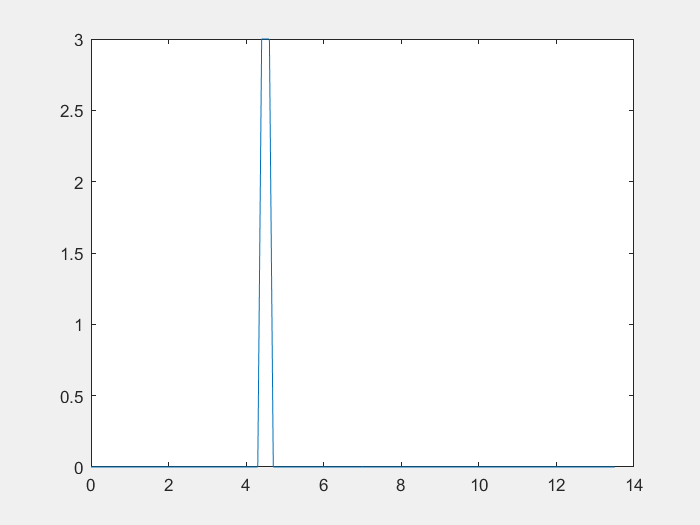

counter = 1;
curtime = 0;
atoc.showDensity();
doneFlights = [0,0,0];
while (curtime < maxTime || ~all(doneFlights))
    for drone = 1:length(uniqueID)
        if(curtime >= minTime)
            if(counter < size(path(drone).traj, 1))
                pos = path(drone).traj(counter, :);
                uas = sim.uas_list(drone);
                uas.gps.lat = pos(1);
                uas.gps.lon = pos(2);
                uas.gps.alt = pos(3);
                uas.gps.commit();
            else
                doneFlights(drone) = 1;
            end
        end
    end
    if(curtime >= minTime)
        counter = counter + 1;
    end
    curtime = curtime + .1;
    sim.step(.1);
end

**Visualing Telemetry Data**

There are multiple different ways to visual telemetry data to track UAS behavior with respect to its planned trajectory. 

The first graph that can be formed is lane trajectory which is displaying the space diagram of the UAS projected distance from the lane itself. This is supposed to be used to get a quick glance whether an object is following the given path. However, this doesn't give a percise represented of whether an objects deviation from the planned path is due to location or speed is not relatively given from this graph. 

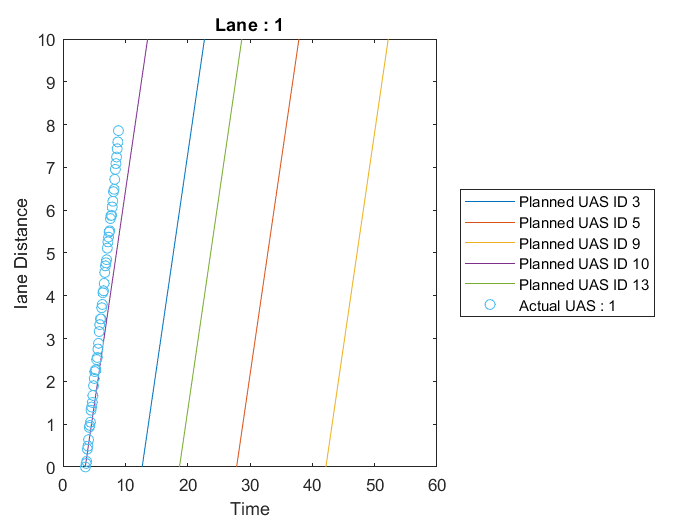

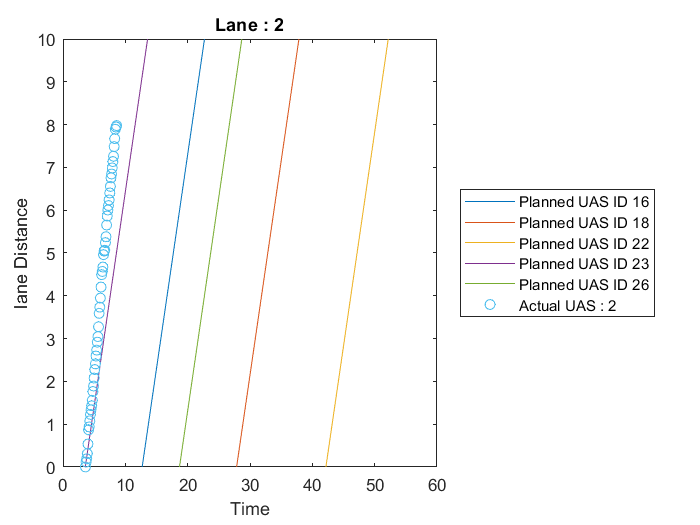

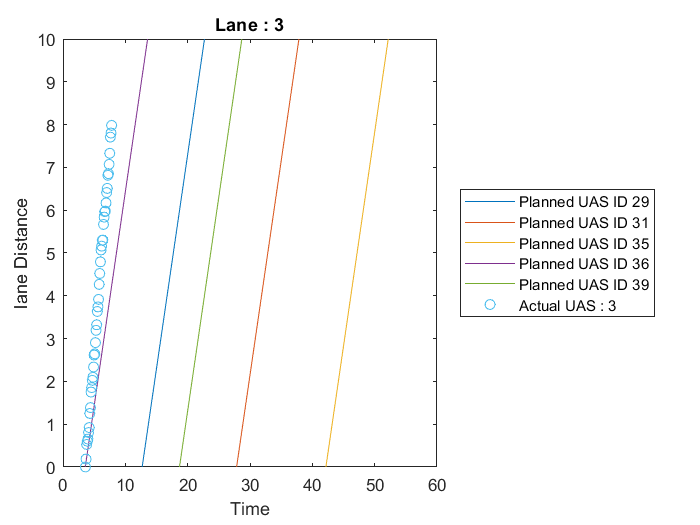

% Grab a random time interval

time = [0 (maxTime + 40)];

% Selection of certain lanes
lanes = ["1", "2", "3"];
% Displays the space lane digrams
atoc.laneTrajectory(lanes, time);

Therefore, the next function is supposed to give a more specific look at the deviation between distance and speed from the telemetry data versus the planned data given a specific time interval to look at. This function takes in specific lanes that is desired to look at given a interval of time. 

% Grabs only a small time interval to specifically look at certain data
% points.
specific_time_interval = [minTime, (maxTime - minTime)/4];
atoc.speedvsdisGraph("1", specific_time_interval);

I also created another function that would invoke both of the previous graphs in one function. That would allow to look at the two different graphs at the same time interval. 

% Function that plots the previous two funciton using just a single
% function

% laneGraphs(lanes, [drone_time(1) drone_time(end)]);

The next information of telemetry data that is presented through graphs would be looking at the density of UAS through the lane system. There are two graphs that will help with the overview of this data. One looks at the number of UAS at a given time in all of the lanes, whereas the other graph will look at the density with a specific lane that was given. Both of these graphs will allow for a time interval that will allow for specfic time or no time interval to allow to see over the whole simulation. 

%% STILL NEEDS TO BE DONE!!! RADAR INFORMATION WILL BE USED FOR THIS.

**Rogue Detection**

This section will show how ATOC class warns about rogue detection